load ./data/peak-theta-slow-wave-5.mat

## Plotting single tunnel pair results histogram

chani=3

chani = 3

figure(1),clf
% calculating magnitude weighted (of xcov) histogram 
edges = -250.2:0.4:250.2;
h=histogram(to_plot{regi,2},edges);
% [histw, vinterval] = histwc(allregionresults{5}{4}{chani,2},...
%     allregionresults{5}{4}{chani,1}, 320, vinterval);
% edges = convertCenters2edges(vinterval);
% Remove 
% histw(max(find(vinterval < 0))) = 0;
% histogram('BinEdges',vinterval,"BinCounts",histw)
% bar(vinterval, histw)
xlabel("<- FB                  Lags(ms)                  FF ->")
xlim([-20 20])
ylabel("Count")

## Subregion-wise lag histogram

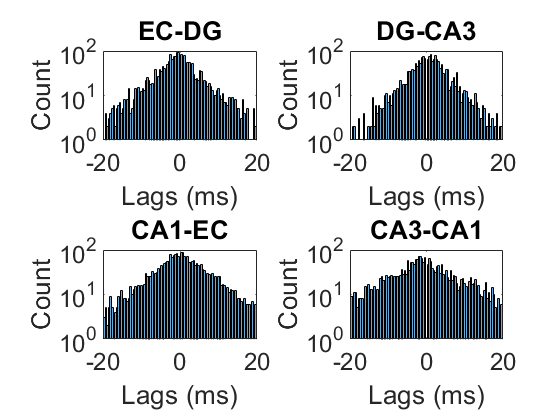

to_plot = cell(4,2);
regList = ["EC-DG", "DG-CA3", "CA3-CA1", "CA1-EC"];
for fi=3:7
    for regi = 1:4
        to_plot{regi,1} = [to_plot{regi,1} cell2mat(allregionresults{fi}{regi}(1:5,1)')];
        to_plot{regi,2} = [to_plot{regi,2} cell2mat(allregionresults{fi}{regi}(1:5,2)')];
    end
end
edges = -250.2:0.4:250.2;
% edges = edges + 0.4;
% 
figOrder = [1 2 4 3];
figure(4), clf
for regi = 1:4
    p(regi)=subplot(2,2, figOrder(regi));
%     [histw, vinterval] = histwc(to_plot{regi,2},to_plot{regi,1}, 320, edges);
%     histw(max(find(histw < 0))) = 0;
%     histogram(to_plot{regi,2}, edges)
%     [edges] = convertCenters2edges(vinterval);
%     bar(vinterval, histw)
    h=histogram(to_plot{regi,2},edges,'Visible',"off");
    binC = h.BinCounts; binE = h.BinEdges;
    binC(max(find(binE < 0))) = 0;
    histogram('BinEdges',binE, "BinCounts",binC)
    xlabel('Lags (ms)')
    ylabel('Count')
    set(gca, 'yscale', 'log')
    title(regList(regi))
end
linkaxes(p,'x')
xlim([-20 20])

## maxlag scatter

figure(7),clf
no_ele = length(speed_samples{1});
scatter([ones(1,no_ele) 2*ones(1,no_ele) 3*ones(1, no_ele) 4*ones(1, no_ele)],...
    200e-6./cell2mat(speed_samples),'filled','ok')
xlim([0.8 4.2])
hold on 
plot([0.8:0.01:4.2], zeros(1, length(0.8:0.01:4.2)), 'r')


## maxlag bar

figure(8),clf
FFBar = zeros(2,4); FBBar = zeros(2,4);
for regi = 1:4
    FFBar(1,regi) = mean(200e-6./speed_samples{regi}(speed_samples{regi} > 0));
    FFBar(2,regi) = stdErr(200e-6./speed_samples{regi}(speed_samples{regi} > 0));
    FBBar(1,regi) = mean(200e-6./speed_samples{regi}(speed_samples{regi} < 0));
    FBBar(2,regi) = stdErr(200e-6./speed_samples{regi}(speed_samples{regi} < 0));
end

bar(1:4, FFBar(1,:),'b')
hold on
errorbar(1:4, FFBar(1,:), FFBar(2,:),'.k')
bar(1:4, FBBar(1,:),'r')
errorbar(1:4, FBBar(1,:), FBBar(2,:),'.k')
xticklabels(regNames)
ylabel '<-FB      Velocity (m/s)      FF->'

## Plot single mea distribution

to_plot = cell2mat(allregionresults{3}{1}(1:5,2)')

to_plot =     3.9200  -15.8000  -11.2800   -8.7200    1.9200   -8.9600    1.0000   -1.1600  106.9200   -1.8000    9.1600   -6.4400   -3.4800  157.4800 -120.6400   -6.8400    5.5600  -26.0800   -0.8400   -3.2000  -19.2400    3.2000   -7.2400  -13.9200   -1.6800   -7.0400   -6.0400   10.0800   -4.2000   -3.2000   -3.3600  -13.9200   -2.4000  -11.3200    0.6000  -11.7600   -3.8400   -6.0800    2.4800   -0.8400   22.8000    3.3600 -156.2000    4.2800  -10.8800   -2.6400    6.5200   19.6400  -92.0400  -88.7200


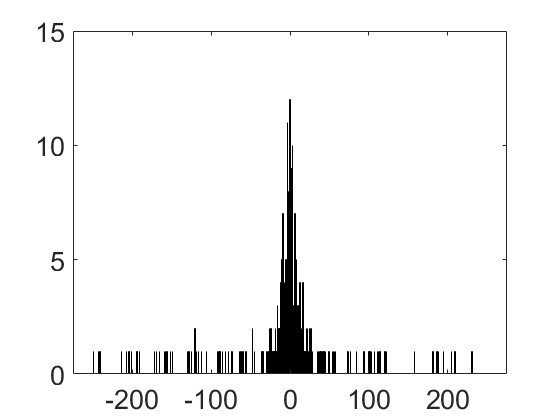

edges = -250.2:0.4:250.2;
figure(10),clf
h=histogram(to_plot,edges);